# Linear Algebra Things

In this notebook we will learn how to do many of things we learned in Linear Algbera, using MATLAB! By the end of this notebook you will be able to 

- Compute the determinant of a square matrix

- Solve a (consistent) system of equations using the `\ `command or the inverse of the matrix (if it exists).

- Find the RREF and nullspace of a given matrix.

- Compute the eigenvalues of a matrix

## Systems of Equations

We have already become familiar with setting up matrices and arrays. You might recall from a linear algebra course that matrices assist us in solving systems of equations such as:

We have many ways to solve this, but the easiest way is to set up the matrix equation $A\vec{x} = \vec{b}$ where $A = \left[\begin{array}{cc} 1 & 1 \\ 2 & -1 \end{array}\right]$ and $\vec{b} = \left[\begin{array}{c} 3 \\ -1 \end{array}\right]$ and multiply both sides by $A^{-1}$. 

First we need to know if the inverse exists. Recall that we can check if a matrix is invertible by finding its determinant. 

You try: Create the matrix `A `defined above. Then use the command `det(A)` to check if it is invertible. Store the value of the determinant in a variable called `det_A`. Is A invertible?

%% Code here.

A = [1 1; 2 -1]

A =      1     1
     2    -1


det_A = det(A)

det_A = -3

Now we can solve the system using the `inv` command. In the code block below, find the inverse of `A` and store it in a variable called `inv_A.`

%% Code here.

inv_A = inv(A)

inv_A =     0.3333    0.3333
    0.6667   -0.3333


The last step is to solve for $\vec{x}$ by multiplying both sides of the equation by $A^{-1}$: 


$$A\vec{x} = \vec{b} \Rightarrow \vec{x} = A^{-1}\vec{b}$$


Create the column vector corresponding to `b. `Then create a variable `x `which gives the solution to this system.

%% Code here.

b = [3 -1]'

b =      3
    -1


x = inv_A*b

x =     0.6667
    2.3333


That seems like a lot of code to solve a single system of equations. There are definitely ways to shorten this, but fortunately MATLAB has a command called `\ `that allows us to solve a system like the one above in just one step. 

You try: Run the code `x2 = A\b`. Do you end up with the same answer?

%% Code here.

x2 = A\b

x2 =     0.6667
    2.3333


Even though, in practice, "matrix division" is not defined, MATLAB uses this built-in function to help solve systems of equations. Remember you can explore the documentation by running the following code.

%% Run this code to explore documentation for \

%doc \

If a system of equations is poorly behaved, MATLAB may still try to solve the system. For example, consider the system:

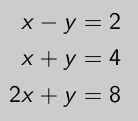

%% Run this code to plot the three equations

xvals = linspace(0,10);
plot(xvals,xvals-2)
hold on
plot(xvals,4-xvals)
plot(xvals,8-2*xvals)
hold off


We can see that this is a system with no solution, but let's see what happens when we use the `\` matrix equation solver. Store your answer in variable called `point`.

%% Code here

A = [1 -1; 1 1; 2 1]

A =      1    -1
     1     1
     2     1


b = [2; 4; 8]

b =      2
     4
     8



point = A\b

point =     3.2857
    1.1429


Why did MATLAB produce a solution in this case? Let's plot `point` and see what's going on:

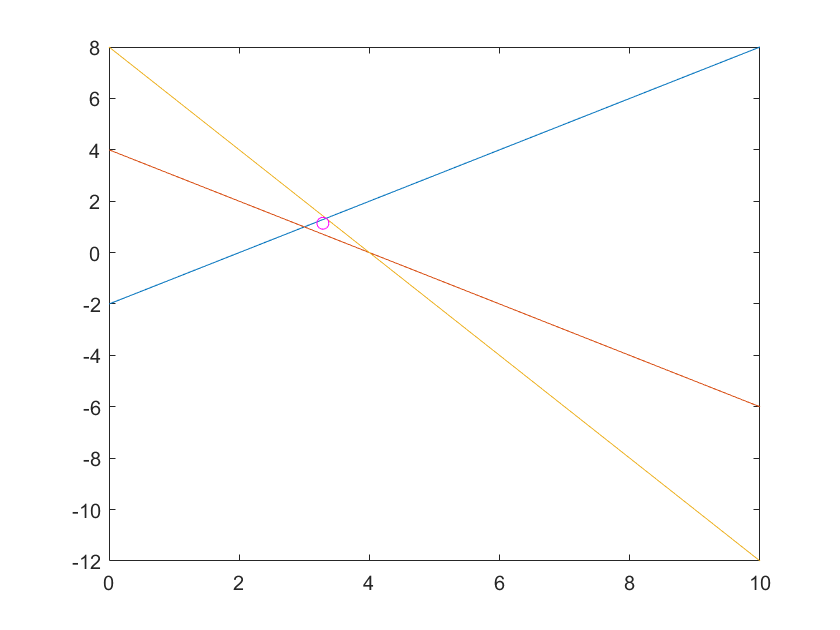

%% Run this code to plot 'point' on the graph above.

hold on
plot(point(1), point(2), 'mo')
hold off

It turns out that, even though there is no solution, MATLAB will still try to find the "best fit" solution to the system!

What if a system has infinitely many solutions? Try using the `\ `command to solve the following system. Store your answer in a variable called y`.`

%% Code here.

A = [1 0 2; 2 1 3]

A =      1     0     2
     2     1     3


b = [1; 5]

b =      1
     5



y = A\b

y =          0
    3.5000
    0.5000


If we were to solve this system by hand, we would see that it has infinitely many solutions, but MATLAB just returns the solution with the greatest number of zeroes in it. 

## RREF and Nullspace

You can also conveniently find the Reduced Row Echelon Form and nullsapce of a matrix with the simple built-in commands `rref `and `null. `

You try: Find the RREF and nullspace of the matrix `A` defined below.

%% Define a matrix A

A = magic(4)

A =     16     2     3    13
     5    11    10     8
     9     7     6    12
     4    14    15     1



%% Code here. 

rref(A)

ans =      1     0     0     1
     0     1     0     3
     0     0     1    -3
     0     0     0     0


null(A)

ans =    -0.2236
   -0.6708
    0.6708
    0.2236


You can convince yourself that this works by multiplying any scalar multiple of `ans` by `A `and checking that you get zero.

## Eigenvalues

Recall that an **eigenvalue** of a matrix is any vector $\vec{v}$satisfying $A\vec{v} = \lambda\vec{v}$ for $\lambda \in \mathbb{R}$. Geometrically, this is just a vector that only gets scaled by the linear transformation $A$.

The built-in function `eig` can be used in multiples ways. Given an $n \times n$ matrix $A$,

- `eig(A)` returns a column vector containing the eigenvalues (note that it is not an eigenvector!)

- `[v,d] = eig(A)` stores a matrix whose columns are eigenvectors in `v `and a diagonal matrix whose diagonal entries are eigenvalues in `d. `

Let's look at an example! 

%% If we just need to know eigenvalues

A = [0 1; -2 -3]

A =      0     1
    -2    -3


eig(A)

ans =     -1
    -2


As expected, we can see that the eigen values of $A$ are $\lambda_1 = -1$ and $\lambda_2 = -2$

%% If we want eigenvectors too!

[v,d] = eig(A)

v =     0.7071   -0.4472
   -0.7071    0.8944


d =     -1     0
     0    -2


Note that order is preserved. That means the first column of `v` corresponds to an eigenvector for $\lambda_1$ and the second column of `v` corresponds to an eigenvector for $\lambda_2$.

Just as a confidence check, we check that this is true. 

First, extract the first column of `v` and store it in a variable called `v1.`

%% Code here.

v1 = v(:,1)

v1 =     0.7071
   -0.7071


Next, extract the (1,1) entry of `d `and store it in a variable called `lam_1`

%% Code here.

lam_1 = d(1,1)

lam_1 = -1

Calculate `A*v1 `and `lam_1*v1` and verify that they are equal. 

%% Code here.

A*v1

ans =    -0.7071
    0.7071


lam_1*v1

ans =    -0.7071
    0.7071


Just as a final note, remember that every eigenvalue has infinitely many eigenvectors. In other words, if $v_1$ is an eigenvector for $A$, so is any multiple of $v_1$. MATLAB will automatically return eigenvectors with length 1. 

%% Find other eigenvectors for v1 by multiplying v1 by any scalar.

e_vec_2 = pi*v1 

e_vec_2 =     2.2214
   -2.2214


A*e_vec_2

ans =    -2.2214
    2.2214


lam_1*e_vec_2

ans =    -2.2214
    2.2214


 That's it for this notebook! 

## Disclaimers and References

*This notebook was written for the *[*The EDGE Program*](https://www.edgeforwomen.org/)* by Anila Yadavalli, Ph. D., 2021.*

*Redistribution of the material contained in this repository is conditional on acknowledgement of Anila Yadavalli, Ph.D.'s original authorship. *

*Some of the exercises in this notebook were inspired by the "Introduction to Linear Algebra with MATLAB" course offered by the *[*MATLAB and Simulink Training Academy*](https://matlabacademy.mathworks.com/)*. *